# Lidar Sensor

Copyright 2018 The MathWorks, Inc.

## Overview

The Lidar Sensor allows you to simulate 2D line-of-sight sensors for visualization and algorithm prototyping. It includes a MATLAB and Simulink interface.

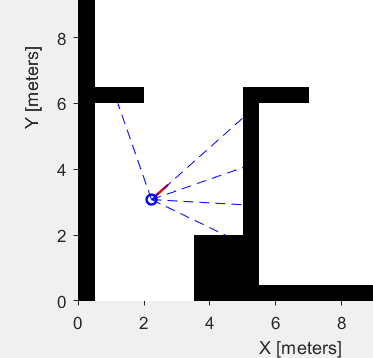

**Properties:**

- **Map: **A [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid)

- **Sensor offset:** A 2-by-1 array of $[x; y]$ offset from the vehicle

- **Scan angles:** An N-by-1 array of scan angles about the $x$-axis, in radians

- **Maximum range:** The sensor maximum range, in meters. Any values outside this range return `NaN`. 

**Inputs:**

- **Pose: **A 3-by-1 array representing the robot pose $[x; y; \theta]$, in meters and radians respectively

**Outputs:**

- **Ranges: **An N-by-1 array of ranges, in meters, corresponding to the **Scan angles** property.

## MATLAB Usage

Create a `LidarSensor` object.

lidar = LidarSensor

lidar =   LidarSensor with properties:

         mapName: ''
    sensorOffset: [0 0]
      scanAngles: [-0.7854 0 0.7854]
        maxRange: 5

Configure the sensor properties.

load exampleMap
lidar.mapName = 'map';
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,11); % 11 scans from -pi/2 to +pi/2
lidar.maxRange = 4;

Simulate the lidar and plot the ranges given the map and vehicle pose.

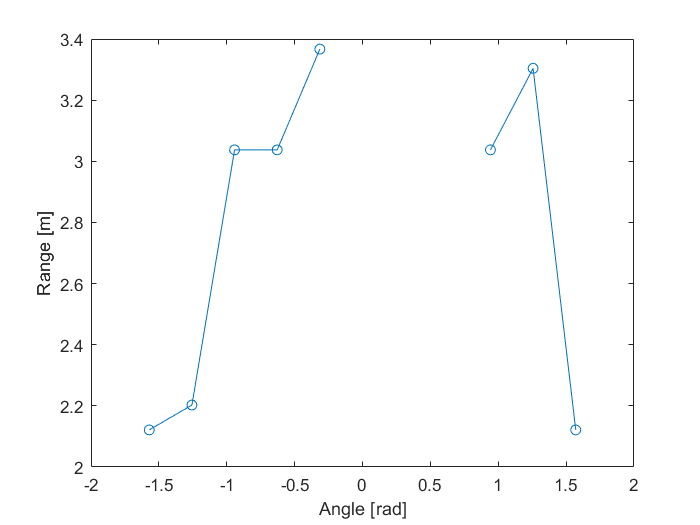

pose = [2; 3; pi/4];
ranges = lidar(pose);
plot(lidar.scanAngles,ranges,'o-');
xlabel('Angle [rad]')
ylabel('Range [m]')

Visualize using the [Robot Visualizer](matlab:edit mrsDocVisualizer2D).

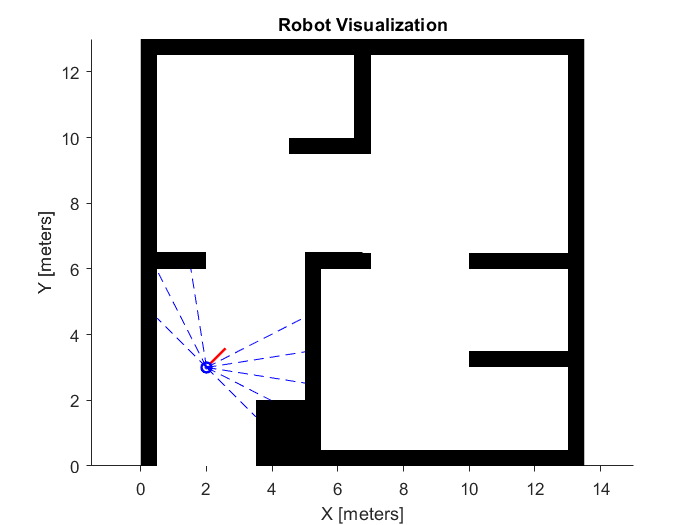

viz = Visualizer2D;
viz.mapName = 'map';
attachLidarSensor(viz,lidar)
viz(pose,ranges)

**Examples**

- [Lidar sensor MATLAB example](matlab:edit mrsExampleLidarSensor)

## Simulink Usage

Use the **Lidar Sensor** block from the **Environments** section of the [block library](matlab:mobileRoboticsLib). 

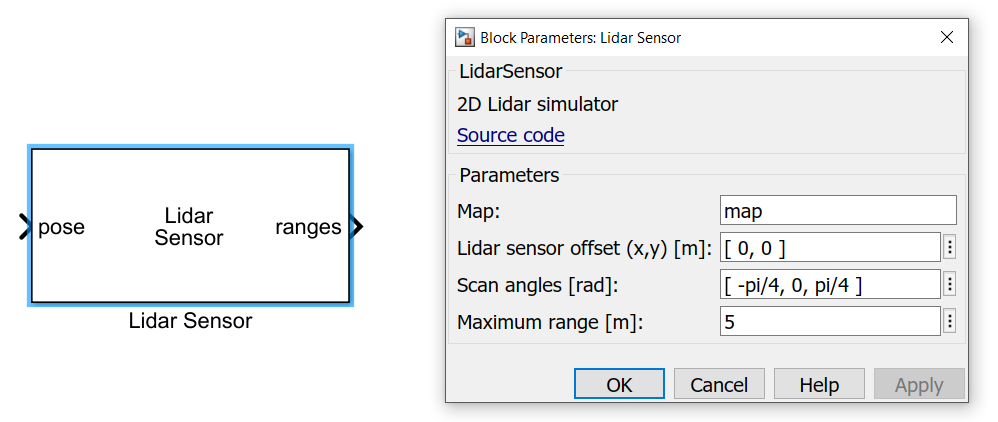

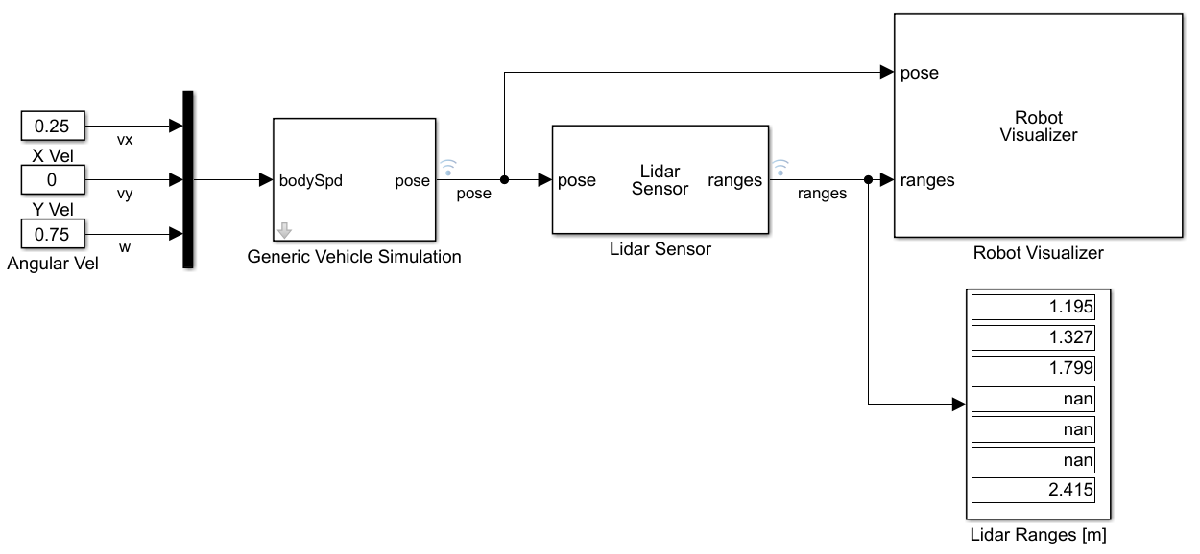

**Examples**

- [Model with Lidar Sensor block](matlab:mrsLidarModel)

- [Model with Lidar Sensor and Object Detector blocks](matlab:mrsLidarAndObjectModel)